# Flujo de carga Newton-Raphson

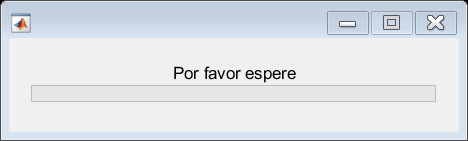

clc
clear all
close all
%Nombre del archivo de excel 

[LIBRO, DIR] =  uigetfile('*.xls', 'archivo excel');

%Letro de espera 

wai = waitbar(0, 'Por favor espere');


% Tipo de nodo -> 1>>Slack 2>>PV 3>>PQ

% Datos nodos 
% Nodos = [bus_1 tipo Pg Qg Pd Qd Bsh Vm Va baseKv Vmax Vmin]
Nodos = xlsread(LIBRO, 'Nodos');

Error using xlsread (line 257)
Worksheet 'Nodos' not found.


% Datos lineas 
% Lineas = [Ni Nf R X bsh/2]

Lineas = xlsread(LIBRO, 'Lineas');

waitbar(0.5, wai);
close (wai)

NR = size(Lineas, 1); % Numero de lineas (cuenta las filas) 
NB = size(Nodos, 1); % Numero de nodos (cuenta las filas)

% Impedancia serie de lineas 
Zlinea = lineas(:, 3) + (sqrt(-1) * Lineas(:, 4));

% Valores iniciales 

Vm_o = Nodos(:, 8); % Magnitud de tensiones iniciales
Va_o = Nodos(:, 9); % Angulo del voltaje 

% Tolerancias 

To1 = 0.001;

% Construccion de la matriz de admitancias nodal (Ybus)

% Elementos fuera de la diagonal

for k = 1:NR
        
    Ybij = -1/Zlinea(k); % Admitancia a partir de la impedancia de linea
    i=Lineas(k,1); % Nodo de comienzo
    j=Lineas(k,2); % Nodo final
    Ybus(i,j) = Ybij; 
    Ybus(j,i) = Ybij;  
    
end

% Elementos de la diagonal 

for i = 1:NB
    for j = 1:NR
        if i == Lineas(j, 1)
            Ybus(i,i) = Ybus(i,i) + (1/Zlinea(j)) + (sqrt(-1)*Lineas(j, 5));
        end
        
        if i==Lineas(j,2)
            Ybus(i,i) = Ybus(i,i) + (1/zlinea(j)) + (sqrt(-1) * Lineas(j,5))
        end
    end
    
    Ybus(i,i) = Ybus(i,i) + Nodos(i,7);
end

figure
spy(Ybus)
title(' Estructura de la Y_(bus')

%Construye el sisemas de ecuaciones de balance nodal 

% contruye variables 
for k= 1:NB
    syms (['V' number2str(k)]);
    Vm(k,1) = eval(['V', num2str(k)]);
    
    syms (['Teta' num2str(k)]);
    Va(k, 1) = eval(['Tesla', num2str(k)]);
    
end

i=sqrt(-1);

% Construye ecuaciones de balance nodal 

for k1=1:NB
    for k2=1:NB
        T(k1, k2) = Va(k2) - Va(k1);
        
        
        syms(['V' num2str(k2)]);
        V_(k1, k2) = eval(['V', num2str(k2)]);
    end
end

G_ = real(Ybus);
B_ = imag(Ybus);

Dp=(Nodos(:,3)-Nodos(:,5)) - ((diag((G_.*V_)*cos(T)).*Vm)+(diag((B_*V_)*sin(T)).*Vm));
Dq=(Nodos(:,4)-Nodos(:,6)) - ((diag((G_.*V_)*sin(T)).*Vm)-(diag((B_*V_)*cos(T)).*Vm));

% Seleccion para los Dp (PV, PQ) y para los Dq

for h=1:NB
    if(Nodos(h,2)==1) %slack
        Dp(h) = [inf];
        Dq(h) = [inf];
        
        Vm(h) = inf;
        Va(h) = inf;
    end
    
    if (Nodos(h,2)==2) %PV
        Dq(h) = [inf];
        Vm(h)= inf;
    end
end


Dp(find(inf==Dp)) = [];
Dq(fin(ind==Dq)) = [];

Vm(find(inf==Vm)) = [];
Va(find(inf==Va)) = [];

X=[Va; Vm]; % Variable de estado desconocidas
Y=[Dp; Dq]; % Sistema de ecuaciones no lineales 

% calculo del jacobiano 

for k1=1:length(Y)
    for k2 = 1:length(X)
        J(k1,k2) = diff(Y(k1) ,X(k2));
    end
end

% Inicia metodo iterativo 

for h=1:NB
    
    evalc(['V' num2str(h) ' = Vm_o(h)'])
    evalc(['Teta' num2str(h) ' = Va_o(h)'])

end

% Calcular delta P y delta Q 

Delta = eval(Y);
ITE =1;

while (ITE<=100) && (sum((abs(Delta) >=To1)) > 0)
    J_o=eval(-1*J); % Evalua jacobiano 
    Delt_T_V = inv(J_o) * Delta; % Calcula Delta_teta y Delta_V
    
    pv=length(find(2==Nodos(:,2))) % Numero de nodos Pv
    pq=length(find(3==Nodos(:,2))) % Numero de nodos Pq
    
    % Actualiza delta_teta
    
    Va_o((find(2<=Nodos(:, 2))))= Va_o((find(2<= Nodos(:,2)))) + Delt_T_V(1: pv+pq);
    
    % Actualiza delta_V
    
    Vm_o((find(3==Nodos(:,2))))=Vm_o((find(3==Nodos(:,2)))) + Delt_T_V(pv+pq+1: length(Delt_T_V));
    
    for h = 1:NB
        evalc(['V' num2str(h) ' = Vm_o(h)'])
        evalc(['V' num2str(h) ' = Vm_o(h)'])

    end
    
    Delata = eval(Y);
    ITE = ITE+1;
end